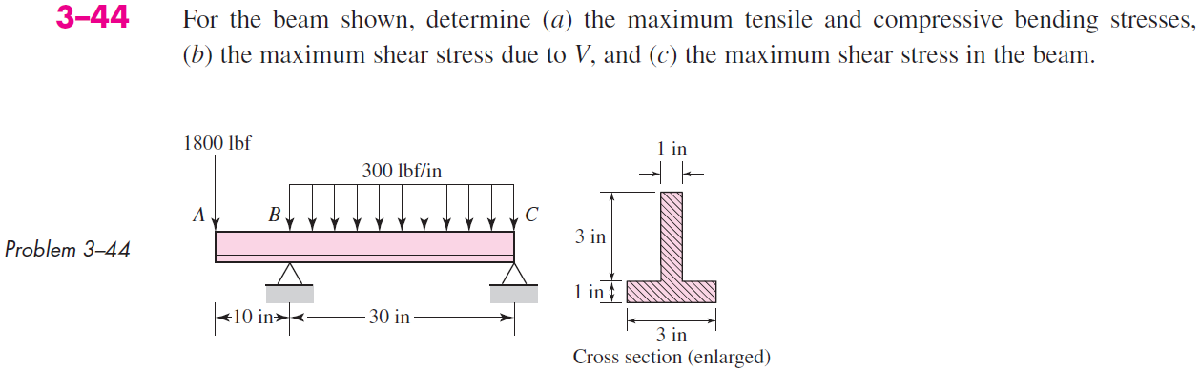

# beam

u = symunit;
b = beam;
b = b.add('reaction', 'force', 'Rb', 10*u.in);
b = b.add('reaction', 'force', 'Rc', 40*u.in);
b = b.add('applied', 'force', -1800*u.lbf, 0);
b = b.add('distributed', 'force', -300*u.lbf/u.in, [10 40]*u.in);
b.L = 40*u.in;

# section properties

yc = [1/2 1+3/2]*u.in;
Ac = [3*1 1*3]*u.in^2;
Ic = [3*1^3 1*3^3]/12*u.in^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic); %#ok
b.I = sum(In);

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{600\,\left(x-10\,\mathrm{in}\right)\,\left(x^{2}+10\,x\,\mathrm{in}+325\,{\mathrm{in}}^{2}\right)}{17\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{in}}^{4}} & \text{ if }x\leq 10\,\mathrm{in}\\ -\frac{25\,\left(x-10\,\mathrm{in}\right)\,\left(x-40\,\mathrm{in}\right)\,\left(x^{2}-58\,x\,\mathrm{in}+60\,{\mathrm{in}}^{2}\right)}{17\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{in}}^{5}} & \text{ if }10\,\mathrm{in}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{1800\,\left(x^{2}+75\,{\mathrm{in}}^{2}\right)}{17\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{in}}^{4}} & \text{ if }x\leq 10\,\mathrm{in}\\ -\frac{100\,\left(x^{3}-81\,x^{2}\,\mathrm{in}+1680\,x\,{\mathrm{in}}^{2}-6550\,{\mathrm{in}}^{3}\right)}{17\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{in}}^{5}} & \text{ if }10\,\mathrm{in}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -1800\,x\,\mathrm{lbf} & \text{ if }x\leq 10\,\mathrm{in}\\ -150\,\left(x-14\,\mathrm{in}\right)\,\left(x-40\,\mathrm{in}\right)\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }10\,\mathrm{in}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -1800\,\mathrm{lbf} & \text{ if }x\leq 10\,\mathrm{in}\\ -300\,\left(x-27\,\mathrm{in}\right)\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }10\,\mathrm{in}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<10\,\mathrm{in}\\ -300\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }10\,\mathrm{in}\leq x \end{array}\right.$$

addvar(y);

# reactions

Rb = r.Rb %#ok

$$Rb = 6900\,\mathrm{lbf}$$

Rc = r.Rc %#ok

$$Rc = 3900\,\mathrm{lbf}$$

clear Rb Rc;

# shear and moment diagrams

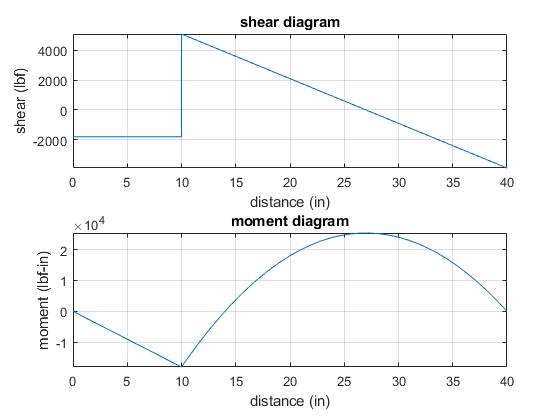

beam.shear_moment(m, v, [0 b.L], {'lbf' 'in'});

# maximum tensile and compressive stresses

assume(E > 0);
x_max = [10*u.in solve(v == 0)];
M_max = m(x_max);
c_tensile = [4*u.in-yn -yn];
c_compressive = [-yn 4*u.in-yn];
sigma_max_tensile = rewrite(-M_max.*c_tensile/b.I, u.psi);
sigma_max_tensile_vpa = vpa(sigma_max_tensile, 5) %#ok

$$sigma\_max\_tensile\_vpa = \left(\begin{array}{cc} 5294.1\,\mathrm{psi} & 4473.5\,\mathrm{psi} \end{array}\right)$$

sigma_max_compressive = rewrite(-M_max.*c_compressive/b.I, u.psi);
sigma_max_compressive_vpa = vpa(sigma_max_compressive, 5) %#ok

$$sigma\_max\_compressive\_vpa = \left(\begin{array}{cc} -3176.5\,\mathrm{psi} & -7455.9\,\mathrm{psi} \end{array}\right)$$

clear sigma_max_tensile_vpa sigma_max_compressive_vpa;
clearassum;

# maximum shear stress

V_max = subs(expression(v,2), x, 10*u.in);
Q_max = ((4*u.in-yn)/2)*(1*u.in)*(4*u.in-yn);
t_min = 1*u.in;
tau_max = rewrite(V_max*Q_max/(b.I*t_min), u.psi)

$$tau\_max = 1875\,\mathrm{psi}$$